20180202

EE646

close all;
clear;
clc;

1. slide3-e.g 2.1-p29

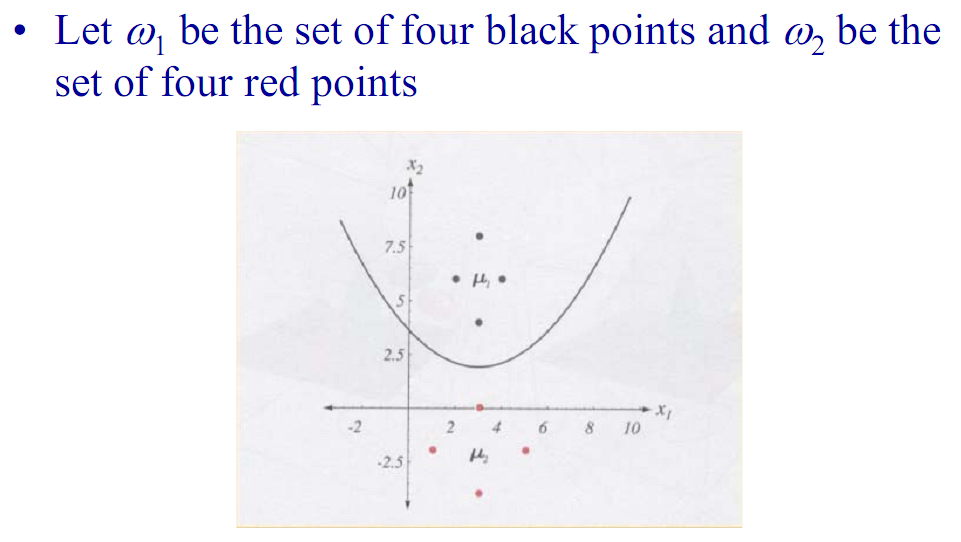

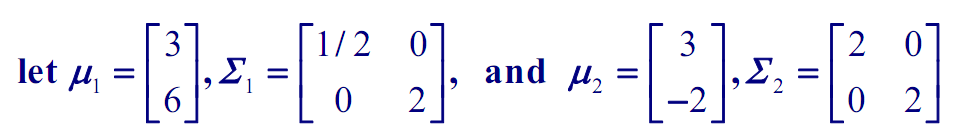

%{

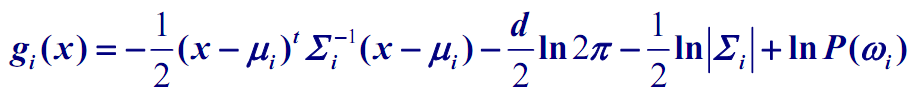

compare each other, if g_x1>g_x2, class w1; if g_x1<g_x2, class w2

mu1 = [3;6]; % colomn
mu2 = [3;-2];
cov1 = [0.5 0;0 2]; % covariance
cov2 = [2 0;0 2];
d = 2;

Pw = 0.5;
syms x1
g1_x = -0.5*(x1-mu1).'*inv(cov1)*(x1-mu1)-d/2*log(2*pi)-0.5*log(det(cov1))+log(Pw);
syms x2
g2_x = -0.5*(x2-mu2).'*inv(cov2)*(x2-mu2)-d/2*log(2*pi)-0.5*log(det(cov2))+log(Pw);
x2 = solve(g1_x == g2_x,x2) % decision boundary
% 2.5*x1^2-18*x1+28.35 = (x2-0.5)^2;
% 2.5*(x1-3.6)^2-(x2-0.5)^2 = 4.05;

figure,
ezplot('2.5*(x2-3.6)^2-(x1-0.5)^2 = 4.05',[-10,10,-10,10]);
hold on;
grid on;
hold off;
return
%}

2. slide3-p29

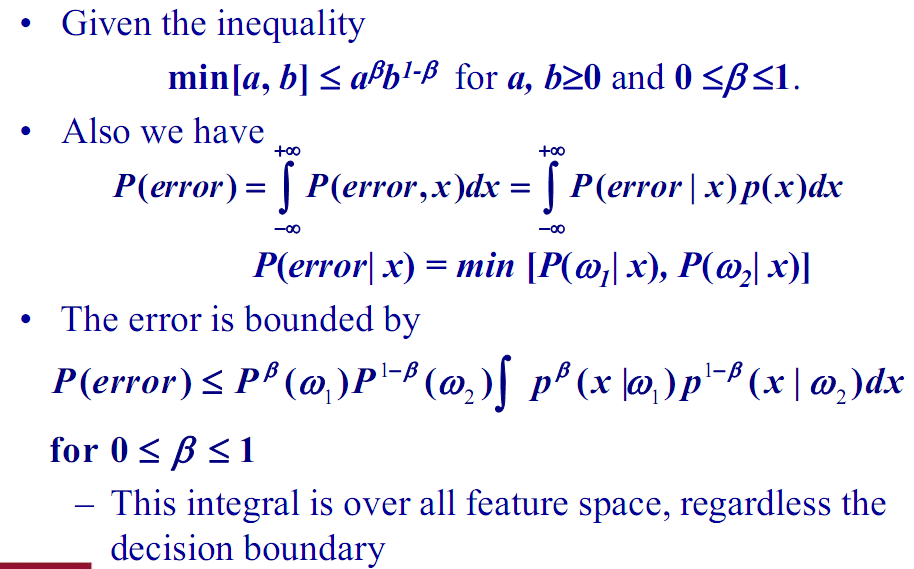

Here is the process,

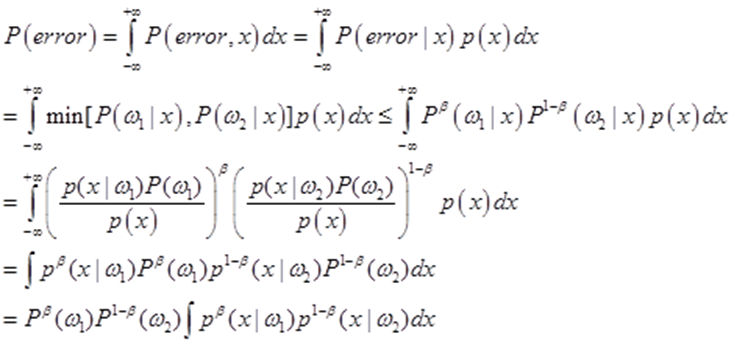

then we get the normal result.

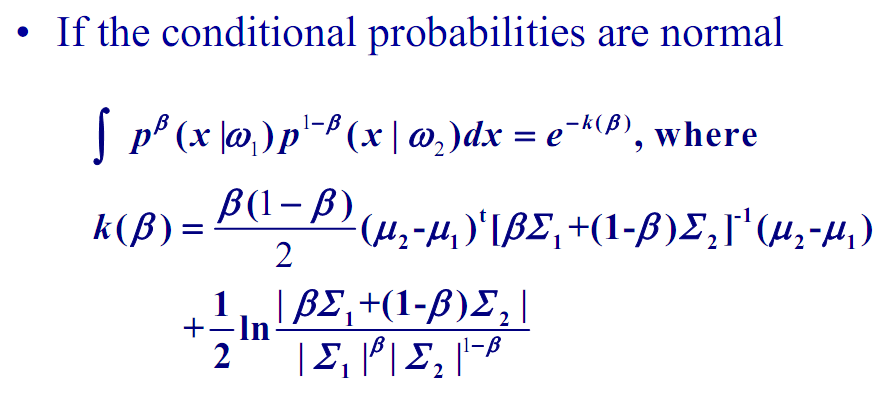

Chernoff bound:

beta is to minimize the funciton exp(-k(beta))

Bhattacharyya bound:

beta  = 0.5

% e.g 2.2-slide3-p39, use the data of e.g 2.1
%{
mu1 = [3;6]; % colomn, mean
mu2 = [3;-2];
cov1 = [0.5 0;0 2]; % covariance
cov2 = [2 0;0 2];
d = 2;
Pw1 = 0.5;
Pw2 = 0.5;

syms b k_b
k_b = b*(1-b)/2*(mu2-mu1).'*inv(b*cov1+(1-b)*cov2)*(mu2-mu1)...
    +0.5*log(det(b*cov1+(1-b)*cov2)/(det(cov1)^b*det(cov2)^(1-b)))

figure,
fplot(matlabFunction(-k_b),[0,1]); % single variable
hold on;
grid on;
hold off;

b_Bha = 0.5;
k_b_Bha = double(subs(k_b,b,b_Bha))
P_error_max_Bha = Pw1^b_Bha*Pw2^(1-b_Bha)*exp(-k_b_Bha)

% [b_Che,n_k_b_Che] = fminsearch(matlabFunction(-k_b),b_Bha) % n_k_b_Che = -k_b_Che
[b_Che,n_k_b_Che] = fminbnd(matlabFunction(-k_b),0,1)
P_error_max_Che = Pw1^b_Che*Pw2^(1-b_Che)*exp(n_k_b_Che)
return
%}

3. e.g 2.3-slide3-p44

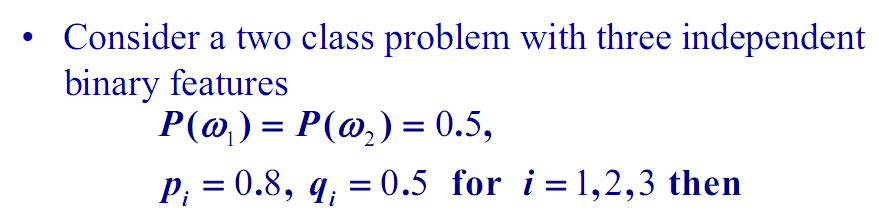

use the formula

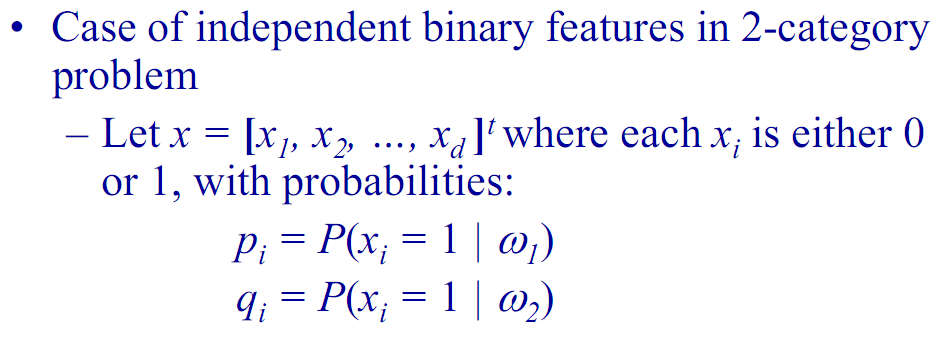 on page 41

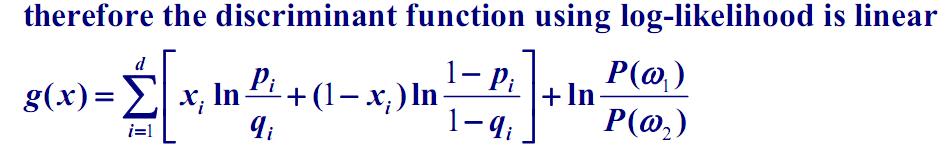 on page 42

compare with 0, if g_x>0, class w1; if g_x<0, class w2

%{
p = [0.8;0.8;0.8];
q = [0.5;0.5;0.5];
Pw1 = 0.5;
Pw2 = 0.5;

% syms g(x1,x2,x3)
% g = x1*log(p(1)/q(1))+(1-x1)*log((1-p(1))/(1-q(1)));
g_x = 0;
for i = 1:length(p)
    eval(['syms x', num2str(i)]);
    a = eval(['x', num2str(i)]);
    g_x = g_x + a*log(p(i)/q(i))+(1-a)*log((1-p(i))/(1-q(i)));
end
g_x = g_x + log(Pw1/Pw2);

x1 = solve(g_x == 0);

figure,
fsurf(matlabFunction(x1));
xlabel('x2');
ylabel('x3');
zlabel('x1');
box on;
% ax = gca;
% ax.XTick = -2*pi:pi/2:2*pi;
% ax.XTickLabel = {'-\pi','-\pi/2','0','\pi/2','\pi'};
% ax.YTick = -2*pi:pi/2:2*pi;
% ax.YTickLabel = {'-\pi','-\pi/2','0','\pi/2','\pi'};
return
%}

4. slide3-p3 univariate normal density

    slide3-p4 mean, variance, entropy

5. slide3-p5 central limit theorem, like significant level

6. slide2-p7 bayes formula

7. slide2-p20 optimal decision

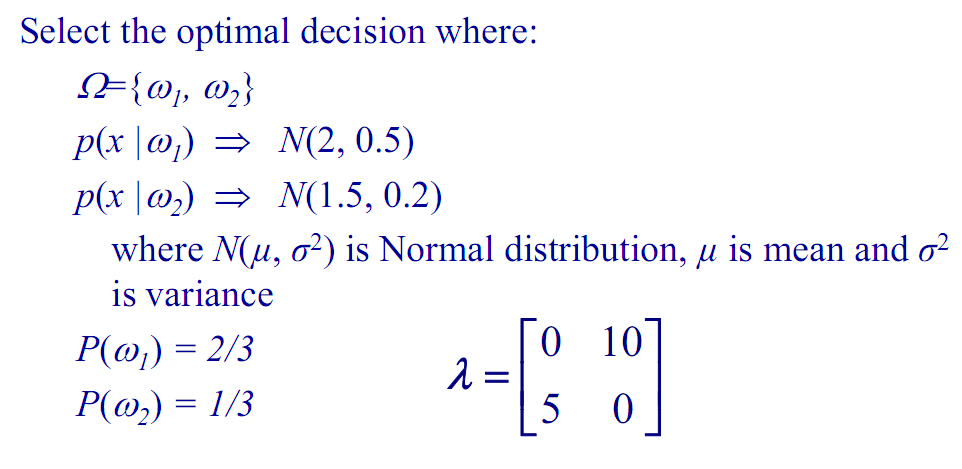

use the formula

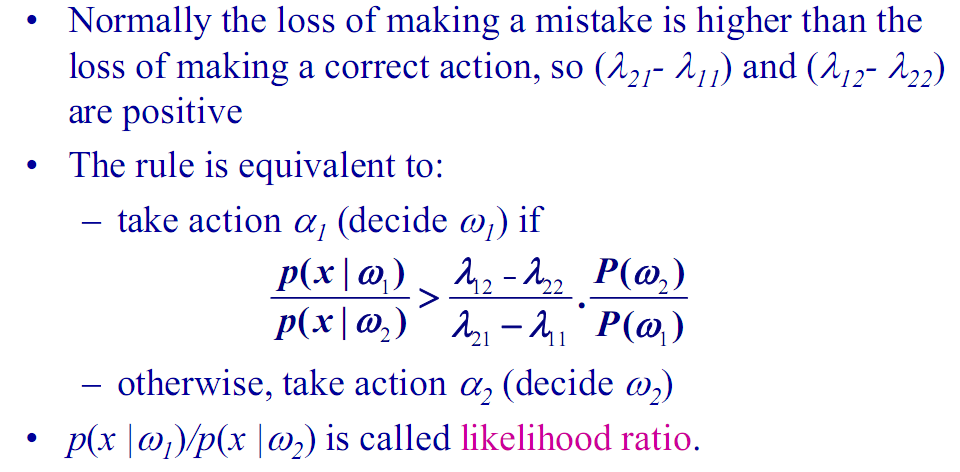

%{
x = -1:0.01:4;
p_w1 = normpdf(x,2,0.5); % p(x|w1), probability density, likelihood
p_w2 = normpdf(x,1.5,0.2);
Pro_w1 = 2/3; % P(w1), probability, prior
Pro_w2 = 1/3;
lamda = [0 10;5 0]; % the loss for error

ratio_p_w = (lamda(1,2)-lamda(2,2))/(lamda(2,1)-lamda(1,1))*(Pro_w2)/(Pro_w1); % likelihood ratio

figure,
plot(x,p_w1);
hold on;
plot(x,p_w2);
legend('w1','w2');

return
%}

8. hw1-1

For a one dimensional 2-class problem with 2 actions ***a***1, ***a***2 , (***a***1: choose ***w***1; ***a***2 choose ***w***2). We assume ***P***(***w***1) = 3/5, ***P***(***w***2) = 2/5, conditional densities 

***p*****(*****x |******w******1*****) ~ *****N*****(0, 1)** and ***p*****(*****x |******w******2*****) ~ *****N*****(2, 4), **

where ***N*****(*****µ*****, *****σ******2*****)** is Normal distribution, ***µ*** is mean and ***σ******2*** is variance.

1.    Sketch the likelihood function for each class (ref. Figure 2.1). Calculate the likelihood value for each class if ***x*****=5**.

2.    Sketch the evidence distribution. Calculate the evidence value if ***x*****=5**.

3.    Sketch the posterior probability function for each class (ref. Figure 2.2). Calculate the posterior probability value for each class if ***x*****=5**.

4.    Sketch the likelihood ratio function (ref. Figure 2.3). Calculate the likelihood ratio value if ***x*****=5**.

5.    Calculate the likelihood ratio threshold for zero-one loss function, i.e. maximum posterior classification 

6.    Calculate the likelihood ratio threshold for the following risk matrix

       w1   w2

a1   0      4

a2   2      0

7.    Following 1.6, sketch the Bayes risk (conditional risk *R*(*αi*|*x*) associated with the action *αi *according to observation *x*) as a function of ***x***. Calculate the Bayes risk value if ***x*****=5**.

%{
% 1
t = -10:0.1:20;
syms x
p_x_w1 = normpdf(x,0,1); % p(x|w1), probability density, likelihood
p_x_w2 = normpdf(x,2,sqrt(4));
ans1_1 = double(subs(p_x_w1,x,5));
ans1_2 = double(subs(p_x_w2,x,5));
% figure,
% plot(t,subs(p_x_w1,x,t));
% hold on;
% plot(t,subs(p_x_w2,x,t),'--');
% hold on;
% legend('p(x|w1)','p(x|w2)');

% 2

use formula

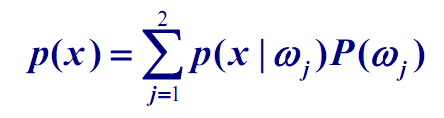

Pro_w1 = 3/5; % P(w1), probability, prior
Pro_w2 = 2/5;
p_x = p_x_w1*Pro_w1+p_x_w2*Pro_w2; % p(x), evidence
ans2 = double(subs(p_x,x,5));
% plot(t,subs(p_x,x,t),'x');
% hold on;
% legend('p(x|w1)','p(x|w2)','p(x)');

% 3

use formula

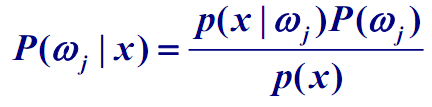

Pro_w1_x = p_x_w1*Pro_w1/p_x; % P(w1|x), probability, posterior
Pro_w2_x = p_x_w2*Pro_w2/p_x;
ans3_1 = double(subs(Pro_w1_x,x,5));
ans3_2 = double(subs(Pro_w2_x,x,5)); % variance !!!!should change!!!
% figure,
% plot(t,subs(Pro_w1_x,x,t));
% hold on;
% plot(t,subs(Pro_w2_x,x,t),'--');
% hold on;
% legend('P(w1|x)','P(w2|x)');

% 4

use formula

ratio_p_x_w = p_x_w1/p_x_w2; %  likelihood ratio function
ans4 = double(subs(ratio_p_x_w,x,5));
% plot(t,subs(ratio_p_x_w,x,t),'x');
% hold on;
% legend('p(x|w1)','p(x|w2)','p(x|w1)/p(x|w2)');

% 5

use formula

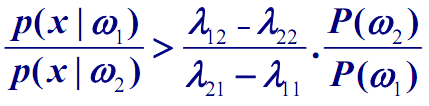

lamda_zo = [0 1;1 0]; % zero-one loss function
theta_a = (lamda_zo(1,2)-lamda_zo(2,2))/(lamda_zo(2,1)-lamda_zo(1,1))...
    *(Pro_w2)/(Pro_w1); % likelihood ratio threshold

% 6

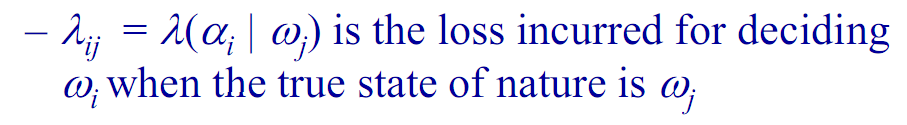

lamda = [0 4;2 0]; % loss function
theta_b = (lamda(1,2)-lamda(2,2))/(lamda(2,1)-lamda(1,1))...
    *(Pro_w2)/(Pro_w1); % likelihood ratio threshold

% 7

use formula

Bayes risk is the shade in the figure

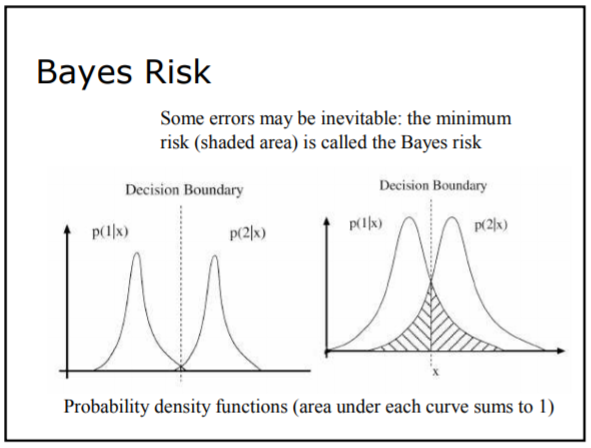

R_a1_x = lamda(1,1)*Pro_w1_x+lamda(1,2)*Pro_w2_x; % R(a1|x)
R_a2_x = lamda(2,1)*Pro_w1_x+lamda(2,2)*Pro_w2_x; % R(a2|x)
R_x = vpa(int(R_a1_x+R_a2_x,x),3) % !!!!!!!!the fomular cannot be integral...
                                    % download the solution of HW1
ans7 = double(subs(R_x,x,5));
ans7_1 = double(subs(R_a1_x,x,5)); % !!! should be integral together 
ans7_2 = double(subs(R_a2_x,x,5));
% figure,
% plot(t,subs(R_a1_x,x,t));
% hold on;
% plot(t,subs(R_a2_x,x,t),'--');
% hold on;
% legend('R(a1|x)','R(a2|x)');
% hold off;
return
%}

9. hw1-2

For a two dimensional 2-class problem, assume both class conditional densities are Gaussian, with the following estimated distribution parameters              

 

1.Calculate the decision boundary.

2. Calculate the Bhattacharyya error bound.

%{ 
% !!! download the homework file check the code 
% 1

use formula

mu1 = [0;0]; % colomn
mu2 = [2;2];
cov1 = [1 0;0 2]; % covariance
cov2 = [1 1;1 2];
d = 2;
Pw1 = 0.25;
Pw2 = 0.75;
syms x1
g1_x = -0.5*(x1-mu1).'*inv(cov1)*(x1-mu1)-d/2*log(2*pi)-0.5*log(det(cov1))+log(Pw1);
syms x2
g2_x = -0.5*(x2-mu2).'*inv(cov2)*(x2-mu2)-d/2*log(2*pi)-0.5*log(det(cov2))+log(Pw2);
% x2 = solve(g1_x == g2_x,x2) % decision boundary
g0 = vpa(simplify(vpa(g1_x == g2_x)),3) % decision boundary
% figure,
% ezplot(g0);
% hold on;
% grid on;
% hold off;

% 2

use formula

syms b
k_b = b*(1-b)/2*(mu2-mu1).'*inv(b*cov1+(1-b)*cov2)*(mu2-mu1)...
    +0.5*log(det(b*cov1+(1-b)*cov2)/(det(cov1)^b*det(cov2)^(1-b)))

figure,
fplot(matlabFunction(-k_b),[0,1]); % single variable
hold on;
grid on;
hold off;

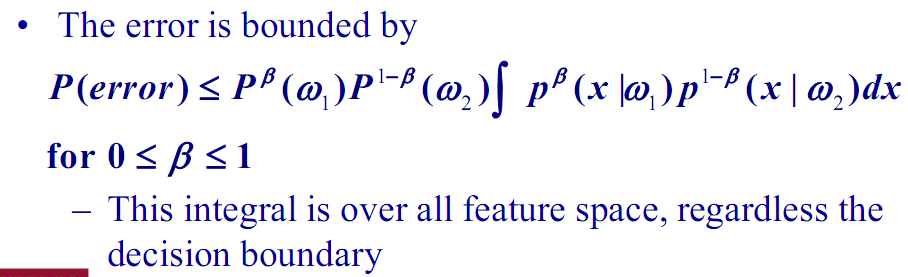

b_Bha = 0.5;
k_b_Bha = double(subs(k_b,b,b_Bha))
P_error_max_Bha = Pw1^b_Bha*Pw2^(1-b_Bha)*exp(-k_b_Bha)

% [b_Che,n_k_b_Che] = fminsearch(matlabFunction(-k_b),b_Bha) % n_k_b_Che = -k_b_Che
[b_Che,n_k_b_Che] = fminbnd(matlabFunction(-k_b),0,1)
P_error_max_Che = Pw1^b_Che*Pw2^(1-b_Che)*exp(n_k_b_Che)
return
%}





























